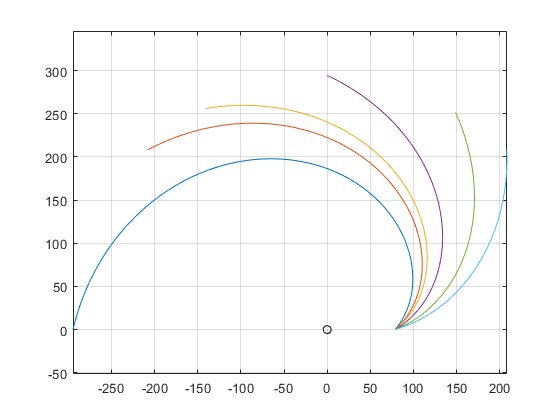

a = 200;
b = 300;
s = 200;
m = a/b;

rMin = 0.25 * (pi/4) * (a + s);
rMax = 0.75 * (pi/4) * (b + s);

thetaMin = deg2rad(0);
thetaMax = deg2rad(45);

c2 = (rMax - rMin)/(thetaMax - thetaMin);
c1 = rMin - c2*thetaMin;

theta = thetaMin:0.01*pi:thetaMax;
y = c1 + c2.*theta;

alphaMax = deg2rad(0);
alphaMin = deg2rad(-120);

alpha = alphaMin:0.01*pi:alphaMax;

kMin = 0.25*(pi/4) * (a + s);
kMax = 0.75*(pi/4) * (b + s);

b2 = (kMax - kMin)/(alphaMax - alphaMin);
b1 = kMin - b2*alphaMin;

z = b1 + b2.*alpha;

plot(0, 0, 'k-o'); hold on;
%plot(z.*cos(alpha), z.*sin(alpha)); hold on;
plot(y.*cos(theta), y.*sin(theta)); hold on;


%plot(kMin.*cos(alpha), kMin.*sin(alpha)); hold on;
%plot(kMax.*cos(alpha), kMax.*sin(alpha)); hold on;
axis equal
grid on